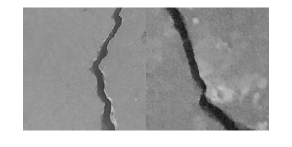

clear
close all
clc
refImg = im2gray(imread("../../data/Data/Concrete Crack Images/00004.jpg"));
newImg = im2gray(imread("../../data/Data/Concrete Crack Images/00143.jpg"));
montage({refImg,newImg})

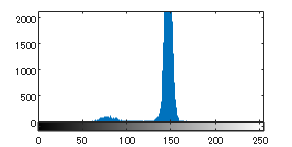

imhist(refImg)

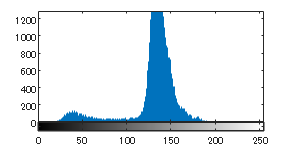

imhist(newImg)

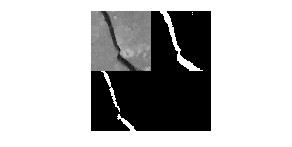


refThresh = graythresh(refImg) * 255;
newImgBW = ~(newImg > refThresh);

matchImgBW = ~imbinarize(imhistmatch(newImg,refImg));
montage({newImg, newImgBW, matchImgBW})